disp("Opgave 6.1")

Opgave 6.1



clc
clear

syms x
f = @(x) -0.9*x^2 + 1.7*x + 2.5;
df = matlabFunction(diff(f, x));


[root, ea, iter] = newtraph(f, df, 5, 0.001)

root = 2.8601

ea = 9.9139e-06

iter = 5

disp("Opgave 6.2")

Opgave 6.2


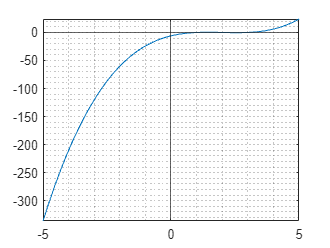


clc
clear

syms x

f = @(x) x.^3 - 6.*x.^2 + 11.*x - 6.1;

df = matlabFunction(diff(f, x));

fplot(f), grid("minor"), xline(0), yline(0)

disp("Svar til 6.2")

Svar til 6.2


[root, ea, iter] = newtraph(f, df, 3.5)

root = 3.0467

ea = 1.8219e-05

iter = 5

disp("Opgave 6.3")

Opgave 6.3


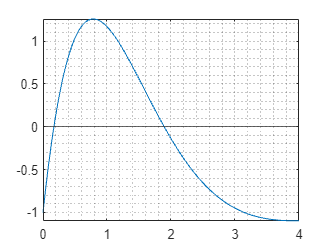


clc
clear
syms x

f = @(x) 7.*exp(-x).*sin(x)-1;

fplot(f, [0, 4]), grid("minor"), xline(0), yline(0)


df = matlabFunction(diff(f, x));

[root, ea, iter] = newtraph(f, df, 0, 0.001, 3)

root = 0.1702

ea = 0.5065

iter = 3


[root, ea, iter] = newtraph(f, df, 2, 0.001, 3)

root = 1.8931

ea = 1.5401e-04

iter = 3

disp("Opgave 6.4")

Opgave 6.4



clc
clear
syms x

f = @(x) -0.9.*x.^2 + 1.7*x + 2.5;

df = matlabFunction(diff(f, x));

[root, ea, iter] = newtraph(f, df, 2, 0.001)

root = 2.8601

ea = 3.2572e-07

iter = 5

disp("Opgave 6.5")

Opgave 6.5



clc
clear
syms x

f = @(x) -2 + 6*x - 4*x.^2 + 0.5*x.^3;
df = matlabFunction(diff(f, x));

x0s = [0.2, 1.8, 5.7, 4.5, 4.43];

for i = 1:length(x0s)
    disp("Resultater for forskellige initial values")
    x0 = x0s(i)
    [root, ea, iter] = newtraph(f, df, x0s(i), 0.001)
end

Resultater for forskellige initial values


x0 = 0.2000

root = 0.4746

ea = 1.2991e-07

iter = 5

Resultater for forskellige initial values


x0 = 1.8000

root = 1.3691

ea = 2.9236e-08

iter = 5

Resultater for forskellige initial values


x0 = 5.7000

root = 6.1563

ea = 1.1506e-04

iter = 4

Resultater for forskellige initial values


x0 = 4.5000

root = 6.1563

ea = 1.0026e-06

iter = 11

Resultater for forskellige initial values


x0 = 4.4300

root = 0.4746

ea = 8.9272e-05

iter = 25